Q=-4.294

Q = -4.2940

n=0.65

n = 0.6500

Cs=-9.8674

Cs = -9.8674

L=-5.7168

L = -5.7168

t=38

t = 38


data_sample=data_3d_0(1:2,:);
data_sample(2,:)=data_3d_0((t+1),:);
f=data_sample(1,:);

% step 1: remove Cstray
ZCs=1./(2i*pi*f*10.^Cs);
data_ZCs=data_sample;
data_ZCs(2,:)=ZCs

data_ZCs = 1.0e+07 *

   0.0300 + 0.0000i   0.0200 + 0.0000i   0.0150 + 0.0000i   0.0100 + 0.0000i   0.0070 + 0.0000i   0.0050 + 0.0000i   0.0030 + 0.0000i   0.0020 + 0.0000i   0.0015 + 0.0000i   0.0010 + 0.0000i   0.0007 + 0.0000i   0.0005 + 0.0000i   0.0003 + 0.0000i   0.0002 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 - 0.0004i   0.0000 - 0.0006i   0.0000 - 0.0008i   0.0000 - 0.0012i   0.0000 - 0.0017i   0.0000 - 0.0023i   0.0000 - 0.0039i   0.0000 - 0.0059i   0.0000 - 0.0078i   0.0000 - 0.0117i   0.0000 - 0.0168i   0.0000 - 0.0235i   0.0000 - 0.0391i   0.0000 - 0.0586i   0.0000 - 0.0782i   0.0000 - 0.1173i   0.0000 - 0.1955i   0.0000 - 0.3909i   0.0000 - 0.7819i   0.0000 - 1.1728i   0.0000 - 2.3456i


Zres=sub_sys(data_sample,data_ZCs,'p')

Zres = 1.0e+05 *

   3.0000 + 0.0000i   2.0000 + 0.0000i   1.5000 + 0.0000i   1.0000 + 0.0000i   0.7000 + 0.0000i   0.5000 + 0.0000i   0.3000 + 0.0000i   0.2000 + 0.0000i   0.1500 + 0.0000i   0.1000 + 0.0000i   0.0700 + 0.0000i   0.0500 + 0.0000i   0.0300 + 0.0000i   0.0200 + 0.0000i   0.0150 + 0.0000i   0.0100 + 0.0000i   0.0060 + 0.0000i   0.0030 + 0.0000i   0.0015 + 0.0000i   0.0010 + 0.0000i   0.0005 + 0.0000i
   0.0014 + 0.0000i   0.0014 + 0.0000i   0.0014 + 0.0000i   0.0014 - 0.0000i   0.0014 - 0.0000i   0.0014 - 0.0000i   0.0014 - 0.0001i   0.0014 - 0.0001i   0.0014 - 0.0001i   0.0014 - 0.0001i   0.0015 - 0.0002i   0.0015 - 0.0002i   0.0016 - 0.0003i   0.0016 - 0.0004i   0.0017 - 0.0005i   0.0018 - 0.0007i   0.0019 - 0.0009i   0.0023 - 0.0014i   0.0028 - 0.0021i   0.0032 - 0.0027i   0.0042 - 0.0041i


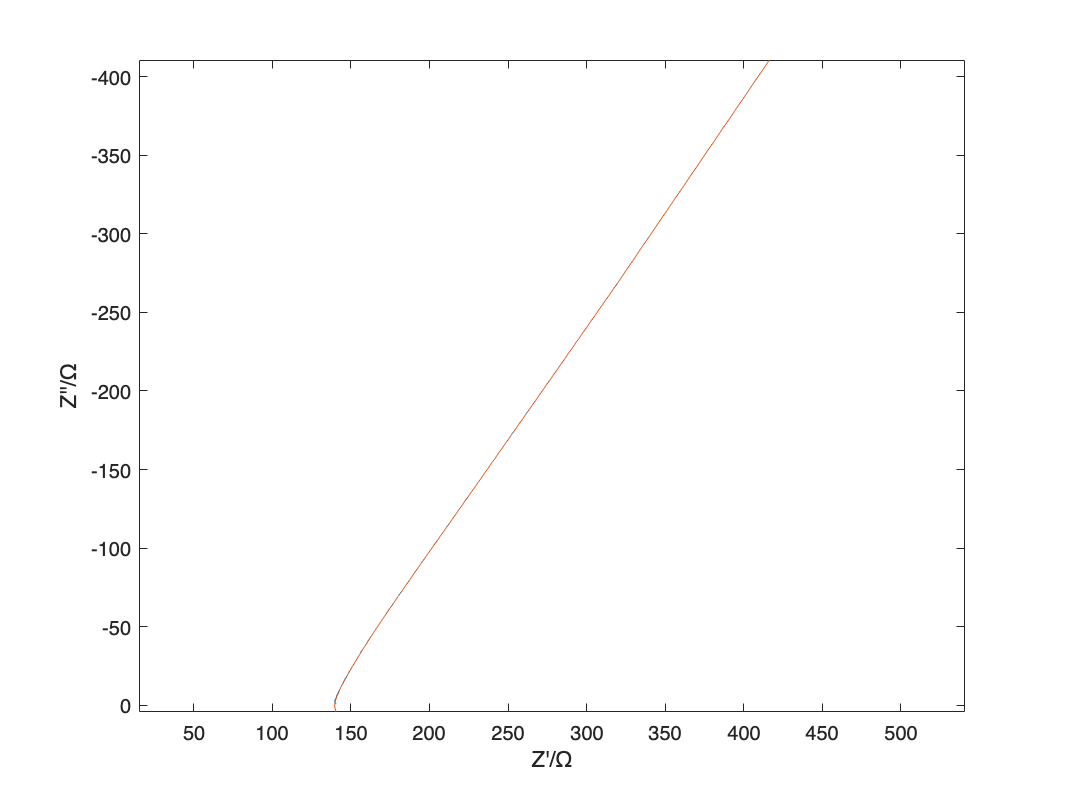


figure()
plotcplx_all_test(data_sample)
hold on
plotcplx_all_test(Zres)


% step 2: remove CPE

data_sample=Zres

data_sample = 1.0e+05 *

   3.0000 + 0.0000i   2.0000 + 0.0000i   1.5000 + 0.0000i   1.0000 + 0.0000i   0.7000 + 0.0000i   0.5000 + 0.0000i   0.3000 + 0.0000i   0.2000 + 0.0000i   0.1500 + 0.0000i   0.1000 + 0.0000i   0.0700 + 0.0000i   0.0500 + 0.0000i   0.0300 + 0.0000i   0.0200 + 0.0000i   0.0150 + 0.0000i   0.0100 + 0.0000i   0.0060 + 0.0000i   0.0030 + 0.0000i   0.0015 + 0.0000i   0.0010 + 0.0000i   0.0005 + 0.0000i
   0.0014 + 0.0000i   0.0014 + 0.0000i   0.0014 + 0.0000i   0.0014 - 0.0000i   0.0014 - 0.0000i   0.0014 - 0.0000i   0.0014 - 0.0001i   0.0014 - 0.0001i   0.0014 - 0.0001i   0.0014 - 0.0001i   0.0015 - 0.0002i   0.0015 - 0.0002i   0.0016 - 0.0003i   0.0016 - 0.0004i   0.0017 - 0.0005i   0.0018 - 0.0007i   0.0019 - 0.0009i   0.0023 - 0.0014i   0.0028 - 0.0021i   0.0032 - 0.0027i   0.0042 - 0.0041i


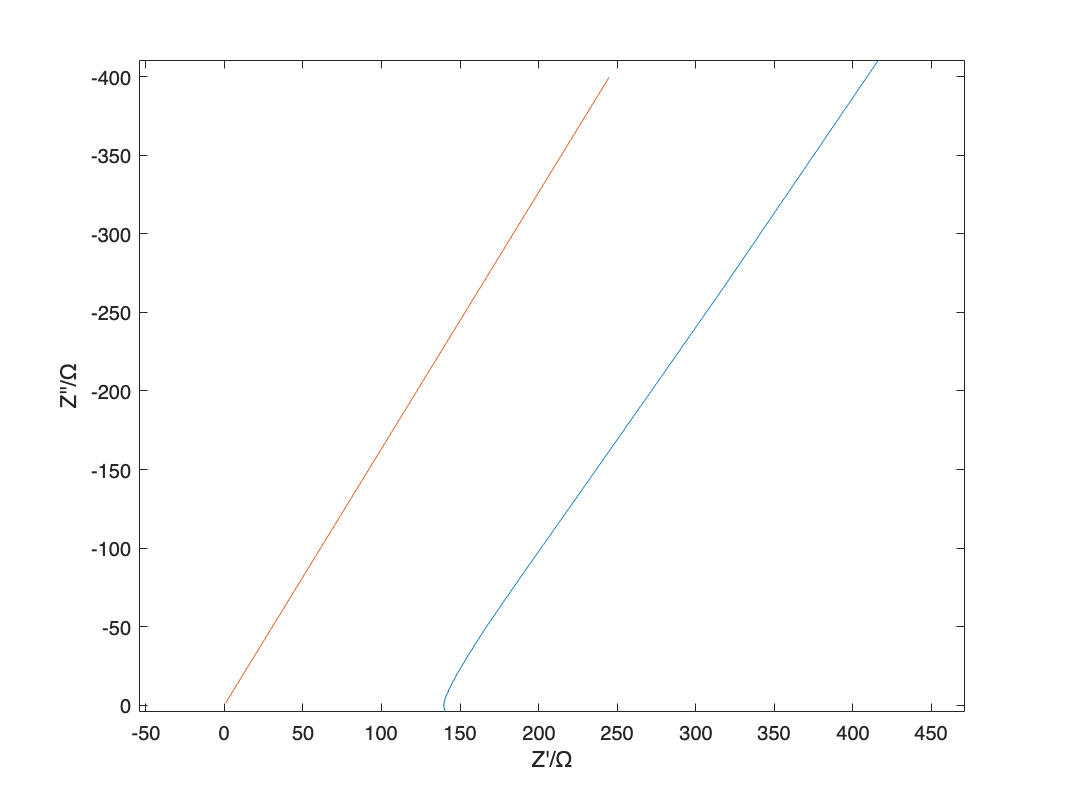


Zcpe=1./((2j*pi.*f).^n.*10.^Q);
data_cpe=data_sample;
data_cpe(2,:)=Zcpe;
Zres=sub_sys(data_sample,data_cpe);
Zres(2,:)=Zres(2,:);

% step 3: remove L
ZL=2i*pi*f*10.^L;
data_ZL=data_sample;
data_ZL(2,:)=ZL;
Zres=sub_sys(Zres,data_ZL);
Zres(2,:)=Zres(2,:);

% Zres(2,:)=1./(1./Zres(2,:)-1/r)
figure()
plotcplx_all_test(data_sample)
hold on
plotcplx_all_test(data_cpe)

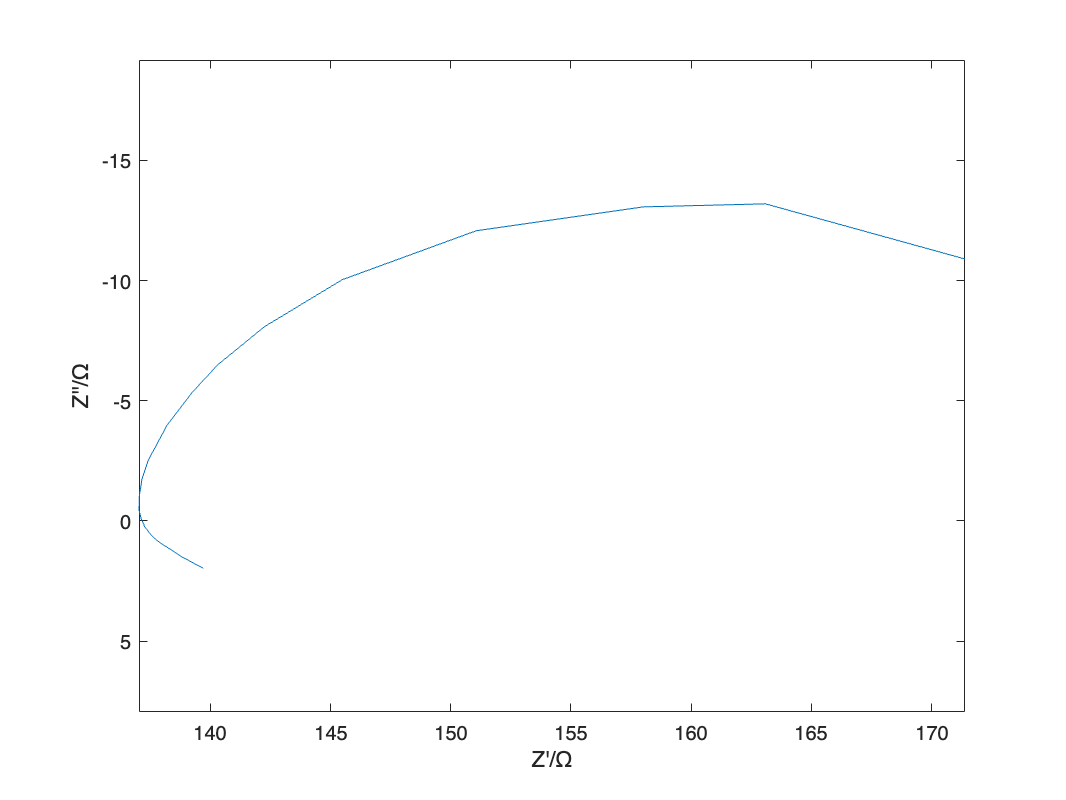

figure()
plotcplx_all_test(Zres)